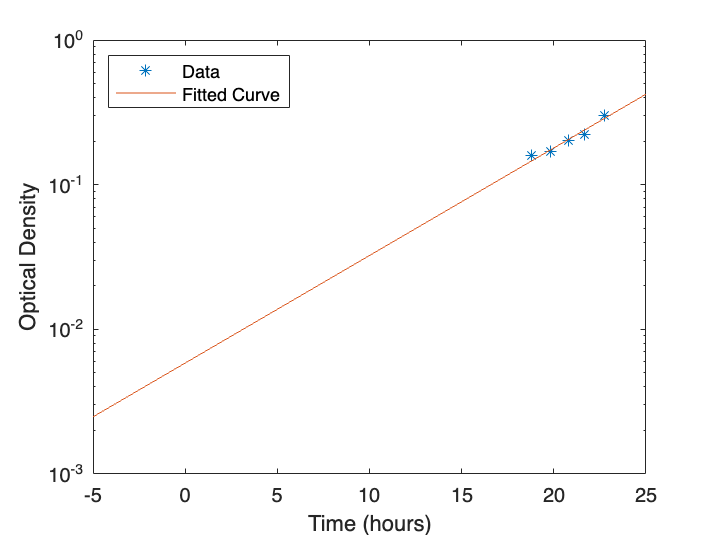

fitobject_old10 =      General model Exp1:
     fitobject_old10(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =    0.005847  (-0.003485, 0.01518)
       b =      0.1712  (0.09674, 0.2456)

gof_old10 = struct with fields:
           sse: 6.4526e-04
       rsquare: 0.9480
           dfe: 3
    adjrsquare: 0.9306
          rmse: 0.0147


clear
clf

data = readmatrix('aerobic_tests.csv');
data_dim = size(data);
num_datapoints = data_dim(1);
addpath ../ % for access to fit_data function

% label data from csv
% exclude first data point
time = data(2:num_datapoints, 1) / 60;     % hours
A = data(2:num_datapoints, 2); % optical density
B = data(2:num_datapoints, 3); % optical density
C = data(2:num_datapoints, 4); % optical density
D = data(2:num_datapoints, 5); % optical density
E = data(2:num_datapoints, 6); % optical density
F = data(2:num_datapoints, 7); % optical density
G = data(2:num_datapoints, 8); % optical density
H = data(2:num_datapoints, 9); % optical density
I = data(2:num_datapoints, 10);% optical density
J = data(2:num_datapoints, 11);% optical density
K = data(2:num_datapoints, 12);% optical density
L = data(2:num_datapoints, 13);% optical density
M = data(2:num_datapoints, 14);% optical density
N = data(2:num_datapoints, 15);% optical density

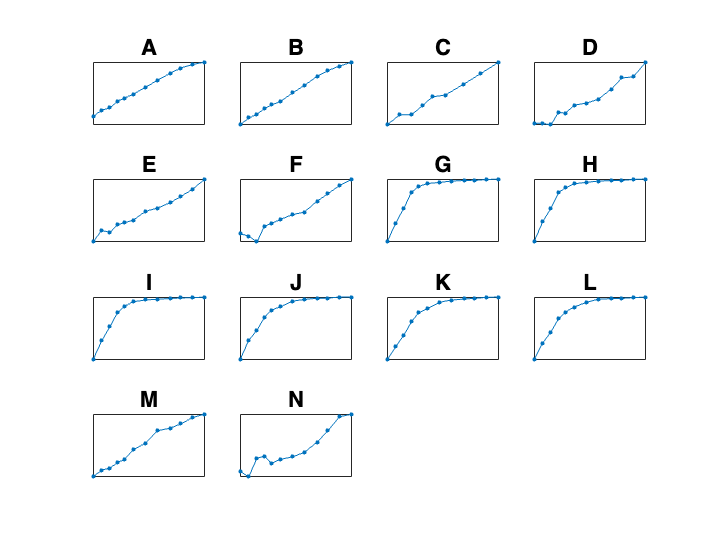

% For quick visualization purposes. Optical density on vertical axis,
% time in hours on horizontal axis. Note that the horizontal axes are
% consistent between graphs, but the vertical axes are not


% I know this is ugly and inefficient but it does the job
clf
figure
subplot(4,4,1)
semilogy(time, A, '.-');
set(gca,'XTick',[], 'YTick', [])
title("A")
hold on
subplot(4,4,2)
semilogy(time, B, '.-');
title("B")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,3)
semilogy(time, C, '.-');
title("C")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,4)
semilogy(time, D, '.-');
title("D")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,5)
semilogy(time, E, '.-');
title("E")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,6)
semilogy(time, F, '.-');
title("F")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,7)
semilogy(time, G, '.-');
title("G")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,8)
semilogy(time, H, '.-');
title("H")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,9)
semilogy(time, I, '.-');
title("I")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,10)
semilogy(time, J, '.-');
title("J")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,11)
semilogy(time, K, '.-');
title("K")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,12)
semilogy(time, L, '.-');
title("L")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,13)
semilogy(time, M, '.-');
title("M")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,14)
semilogy(time, N, '.-');
title("N")
set(gca,'XTick',[], 'YTick', [])

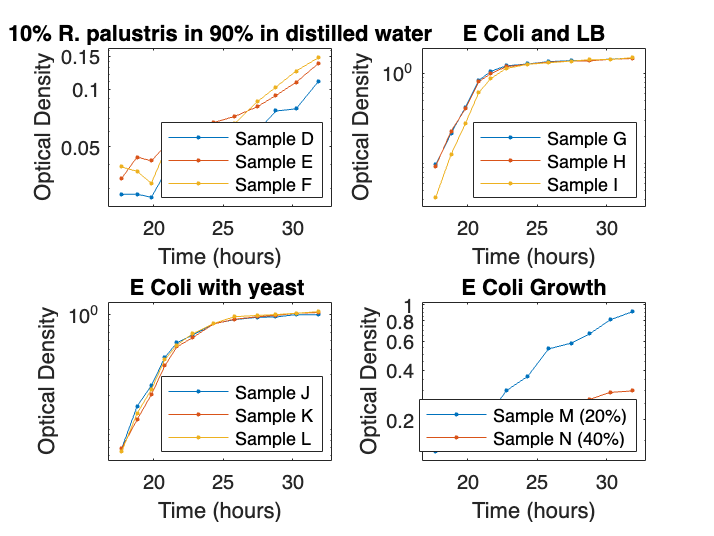

% Growth graphs separated into groups w/ same setup


% R plaus 10% in 90% in distilled water
clf
figure
subplot(2,2,1)
semilogy(time, D, '.-');
hold on
semilogy(time, E, '.-');
semilogy(time, F, '.-');
title("10% R. palustris in 90% in distilled water")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample D","Sample E","Sample F", ...
    "location", "southeast")
axis padded
hold off

% E Coli and LB
subplot(2,2,2)
semilogy(time, G, '.-');
hold on
semilogy(time, H, '.-');
semilogy(time, I, '.-');
title("E Coli and LB")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample G","Sample H","Sample I", ...
    "location", "southeast")
axis padded
hold off

% E Coli with yeast 
subplot(2,2,3)
semilogy(time, J, '.-');
hold on
semilogy(time, K, '.-');
semilogy(time, L, '.-');
title("E Coli with yeast ")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample J","Sample K","Sample L", ...
    "location", "southeast")
axis padded
hold off

% E Coli 20% and 40%
subplot(2,2,4)
semilogy(time, M, '.-');
hold on
semilogy(time, N, '.-');
title("E Coli Growth")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample M (20%)","Sample N (40%)",...
    "location", "southeast")
axis padded
hold off